% This models the 436 CP16 antenna .
% Parameter : Datasheet / Model
% Gain : 13.3 dBic / 13.3 dBi
% Front -to - back : 15 dB / 16.6 dB
 % HPBW : 42.0 / 48.0
d1 = dipole ('Length' ,12.625*.0254 , 'Width' , cylinder2strip((3/32)*.0254) ,...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d2 = dipole ('Length' ,12.250*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
 'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d3 = dipole ('Length',11.937*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d4 = dipole ('Length' ,11.750*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
 'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d5 = dipole ('Length' ,11.531*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d6 = dipole ('Length',11.375*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt',90,'TiltAxis' ,[0 1 0]);
r = dipole ('Length' ,13.687*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
dip=dipole('Length',13.625*0.0254,'Width',cylinder2strip((3/32)*0.0254),...
'Tilt',90,'TiltAxis' ,[0 1 0]) ;
uhf = quadCustom('Exciter',dip,...
'Director', {d1 d2 d3 d4 d5 d6 } ,...
'DirectorSpacing', [(17 -14.562) (23.313 -17) (31.875 -23.313)...
(41.813 -31.875) (51.563 -41.813) (61 -51.563)].*0.0254 ,...
'Reflector' ,{r} ,...
'ReflectorSpacing', 2.562*0.0254 ,...
'BoomLength', 65.75*0.0254 ,...
'BoomWidth', cylinder2strip((1/2)*0.0254) ,...
'BoomOffset' ,[0 0.005 (65.75/2 -14.562)*0.0254] ,...
'Tilt' ,90 ,...
'TiltAxis' ,[0 1 0]);

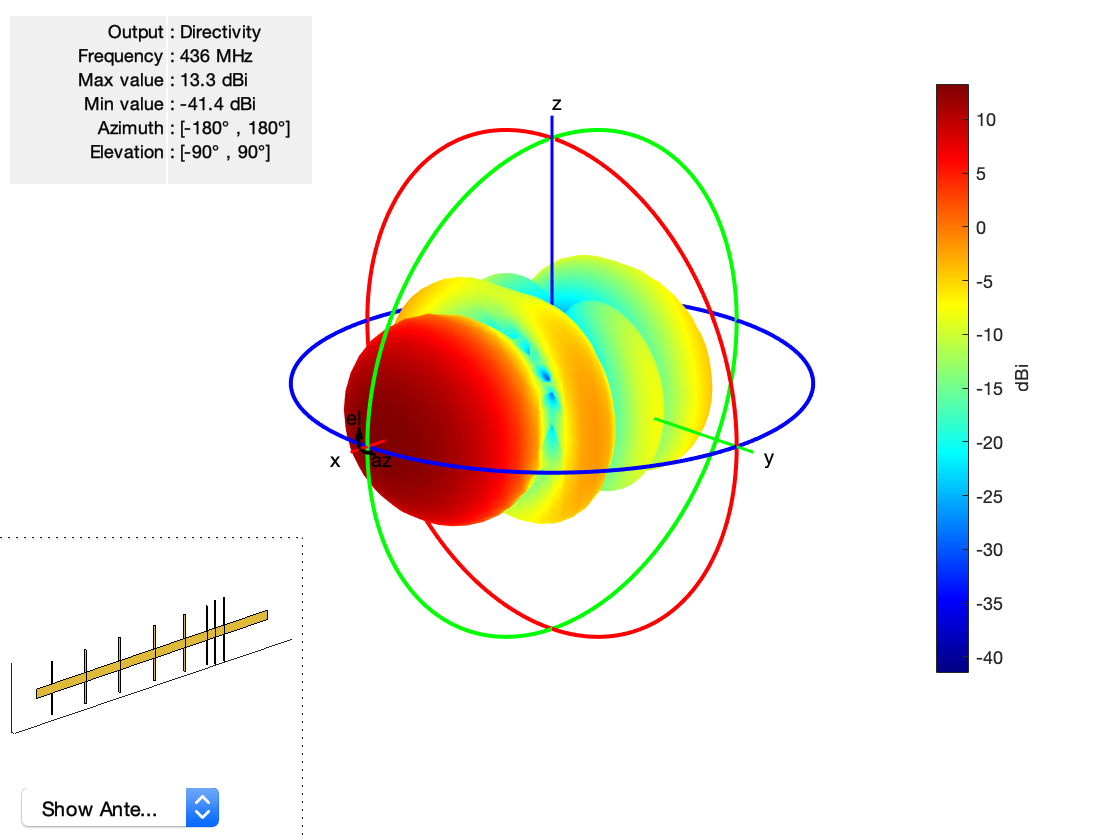

figure
pattern(uhf ,436e6)

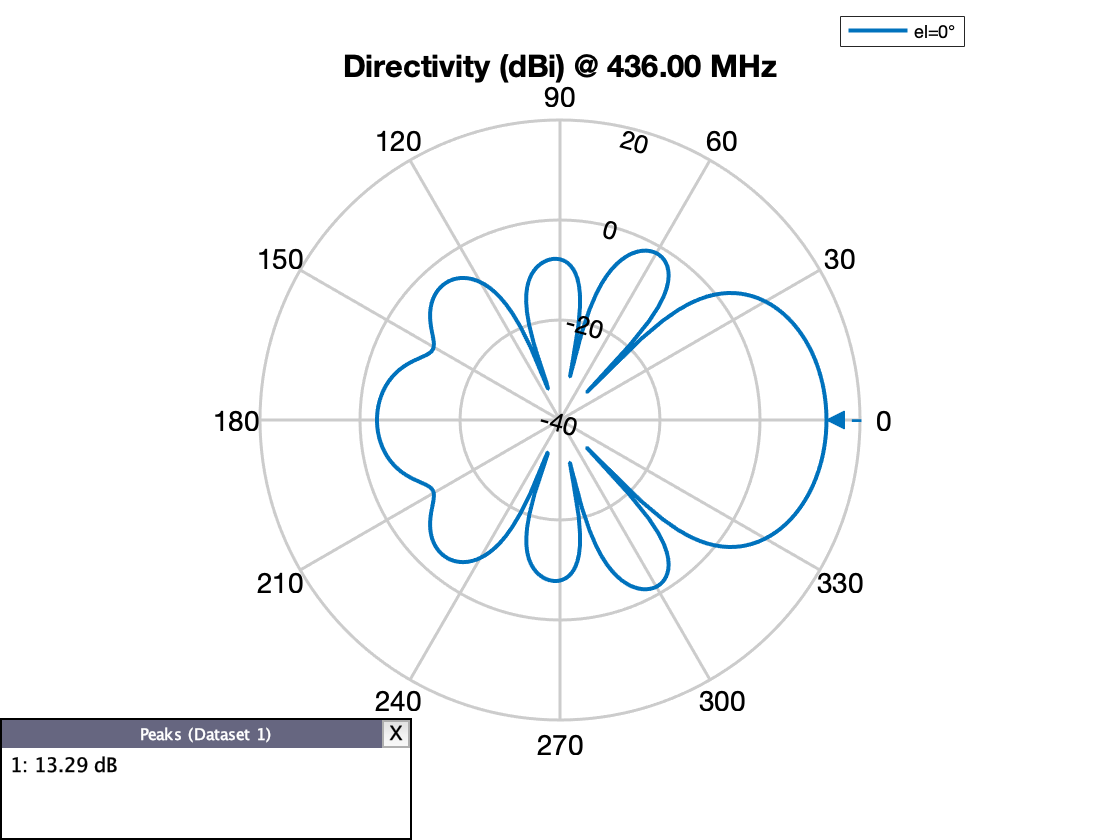

figure
patternAzimuth (uhf ,436e6);

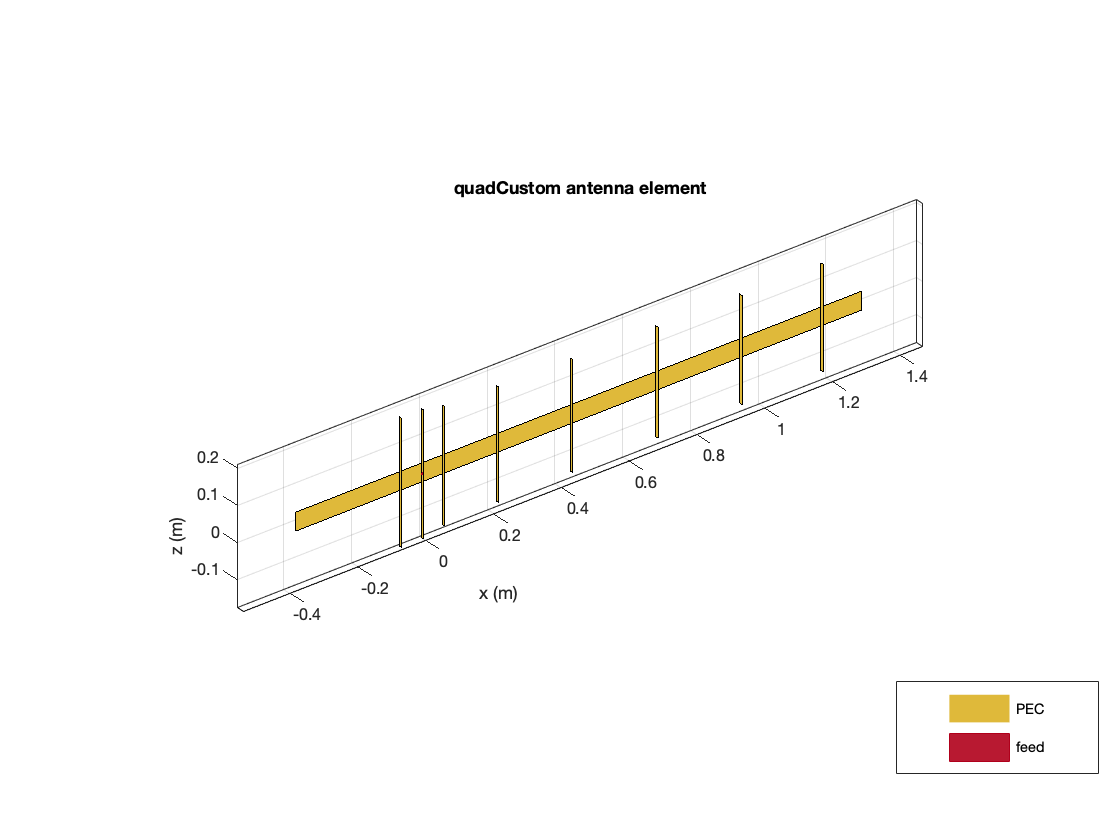

figure
show (uhf)

fc =435e6; % For UHF = 435e6 , f o r VHF = 146 e6
c = physconst ('LightSpeed');
ant = uhf;
wavelength = c/fc;
elempos=[ -4.29842954311602 2.3546283467097275...
-7.912256000697484 6.438089637760736 4.5776928224254405...
0.6114083762343334 4.3491466713765625 -6.978679013358557...
6.964229482301359 -2.638378749849286 3.8559250832060386...
-2.5572254930149825 -1.3326465838541584 -6.266881989810605...
0.6070051482277137 -7.4675031752086 0.40120979820752467...
7.536624862621524 3.053825753918666 -1.3515337413772084;...
-6.4414991413467675 -7.7981345390623655 -6.290064521443938...
7.702090051841351 -3.7192665716494435 -1.25566398435347...
0.1276082372219225 2.252177479694957 3.2949516453081067...
4.215300908212189 4.157452247154753 -2.728518947281204...
6.989500794141902 -1.4034674523616246 -4.972862289530184...
7.85681577520325 4.181478934647917 -1.3631776200798864...
7.921167173856714 1.4380251430317603 ; 0 0 0 0 0 0 0 0 0 0 0 0 ...
0 0 0 0 0 0 0 0 ];
% elempos=[1 2 1 2;0 0 1 1; 0 0 0 0];

% Create an arbitrary array which takes i n custom coordinates .
arbitrary = phased.ConformalArray(...
'ElementPosition', elempos,...
'ElementNormal', [0;90] ,...
'Element',ant);

% This i s a uniformly spaced (5 x4) array with 3m spacing between each
% antenna . Uncomment to analyze .
% arbitrary = phased.ConformalArray(...
% 'ElementPosition', [0 3 6 9 0 3 6 9 0 3 6 9 0 3 6 9 0 3 6 9;...
% 0 0 0 0 3 3 3 3 6 6 6 6 9 9 9 9 12 12 12 12;...
% 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0] ,...
% 'ElementNormal', [0;90] ,...
% 'Element',ant);

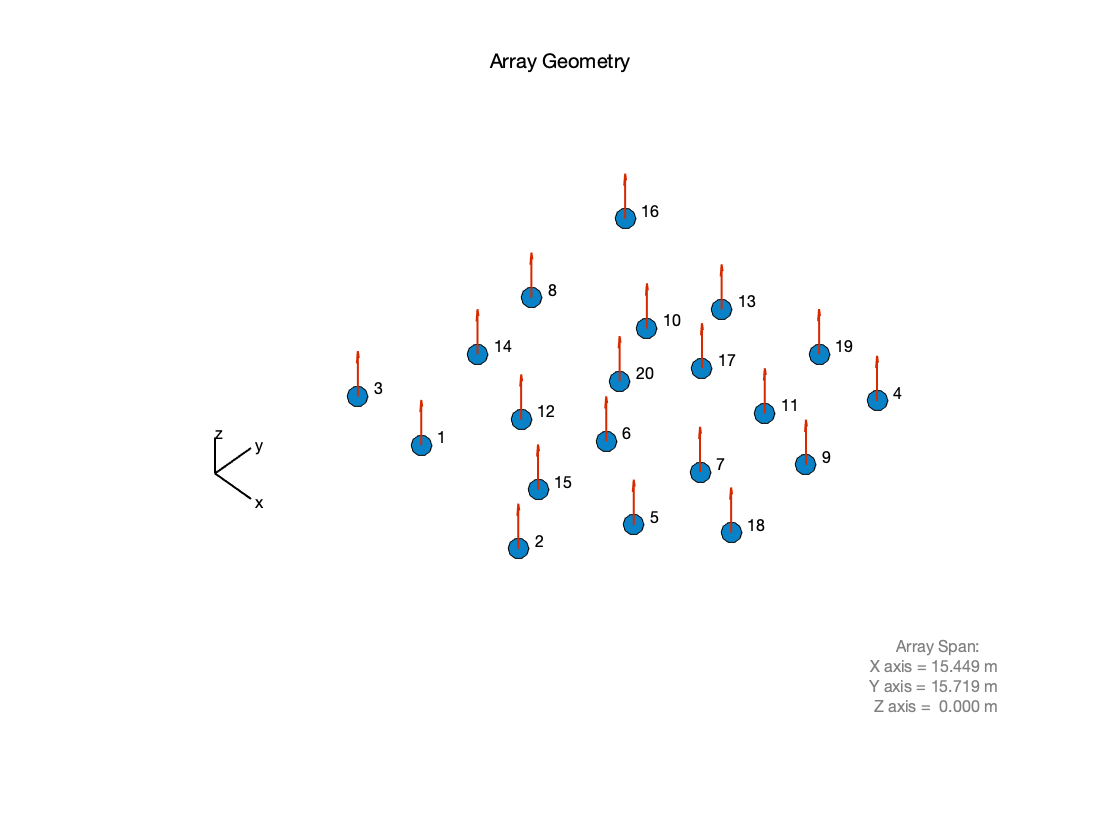

% View the array elements by uncommenting below .
figure
viewArray ( arbitrary ,'showNormals',true ,'ShowIndex','All')

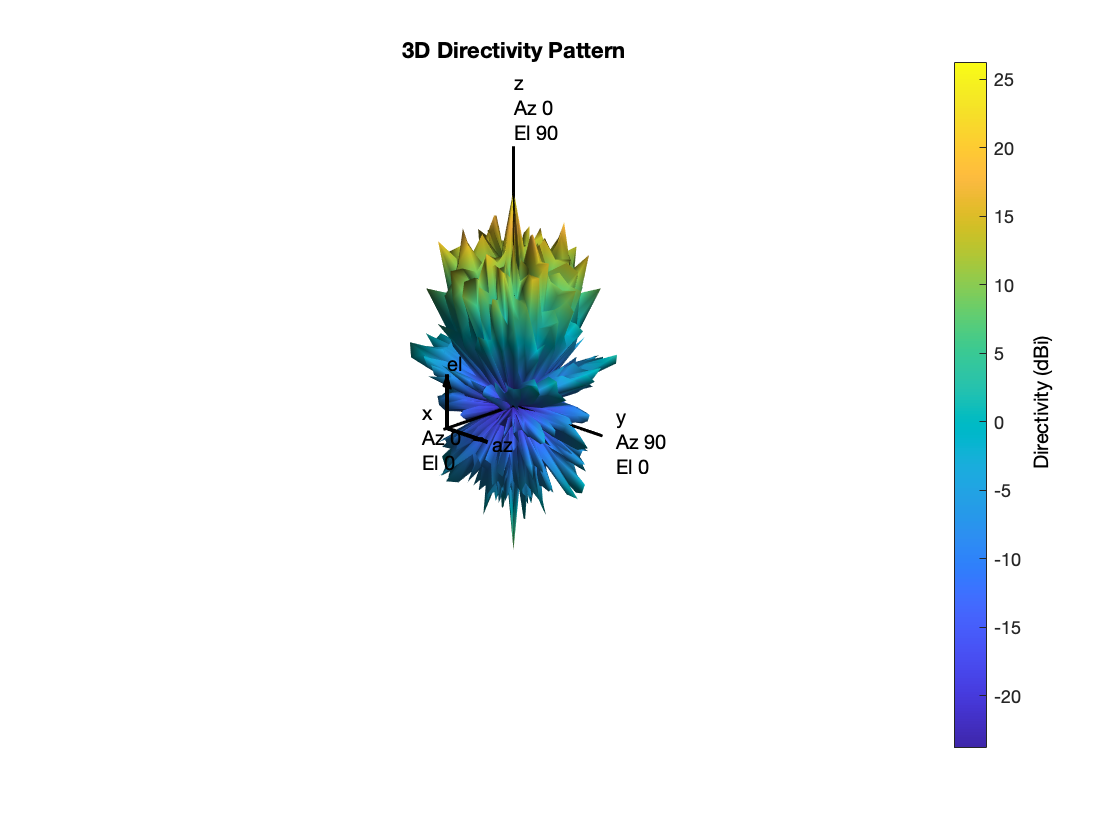

% Look at the overall array ’s beam pattern .
figure
pattern (arbitrary,fc);

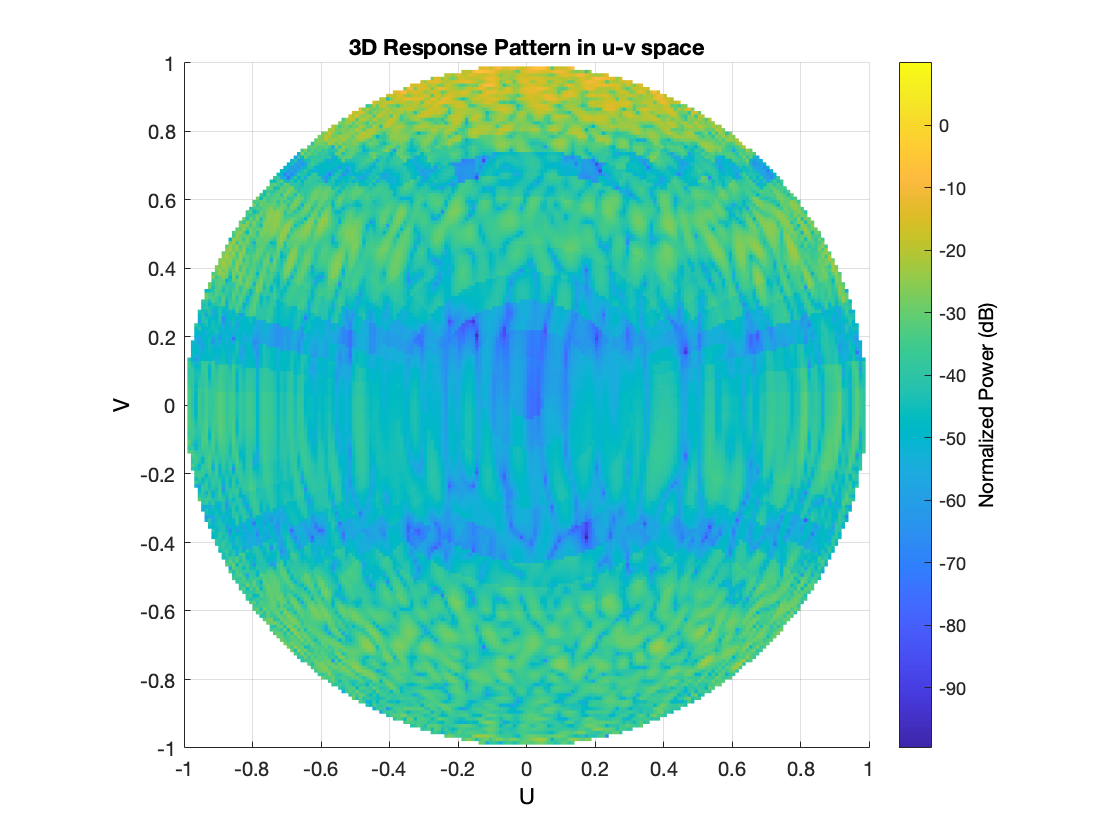

pattern(arbitrary,fc,'PropagationSpeed',c,'Type','powerdb',...
    'CoordinateSystem','UV');

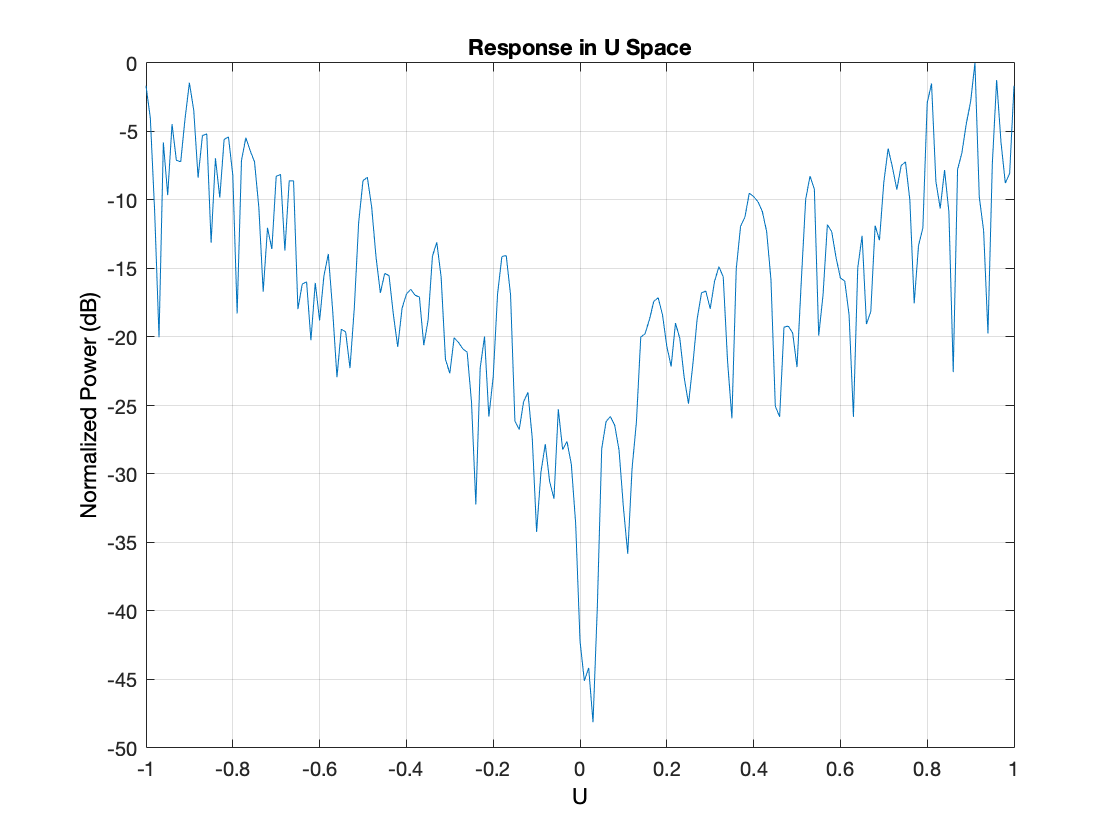

pattern(arbitrary,fc,-1:0.01:1,0,'PropagationSpeed',c, ...
    'CoordinateSystem','UV','Type','powerdb')
axis([-1 1 -50 0]);

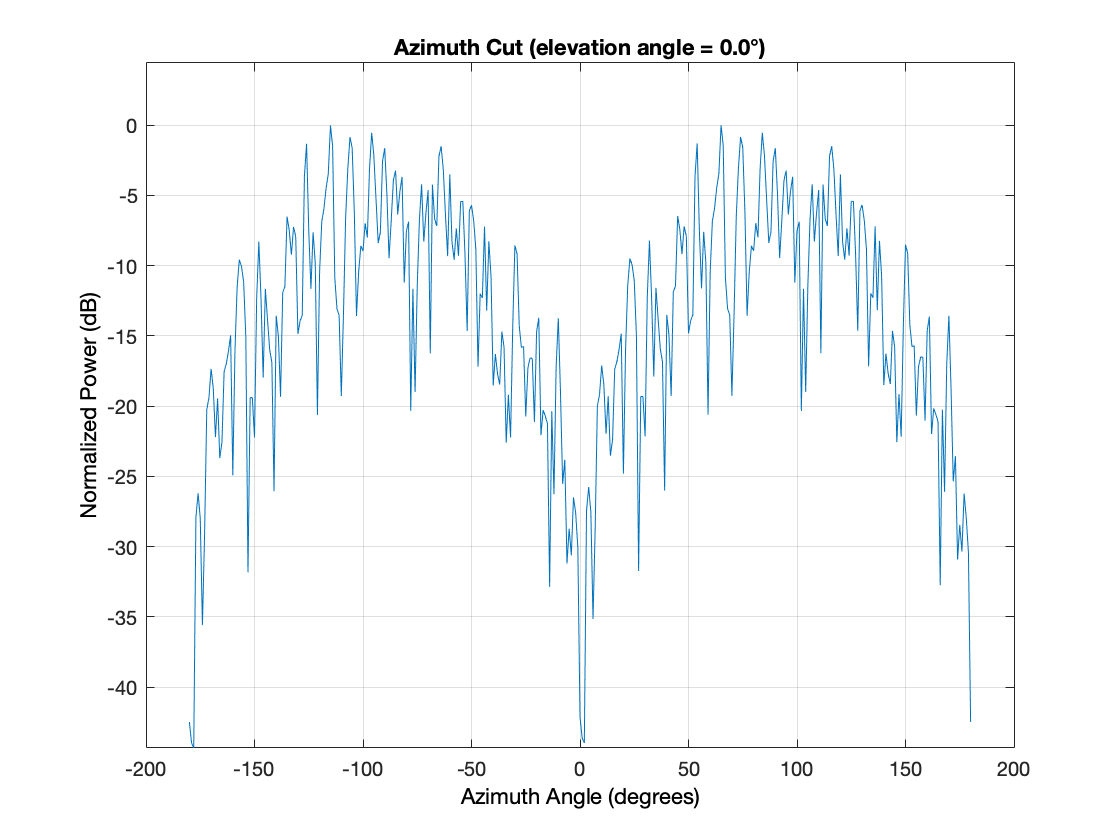

plotResponse(arbitrary,fc,c)

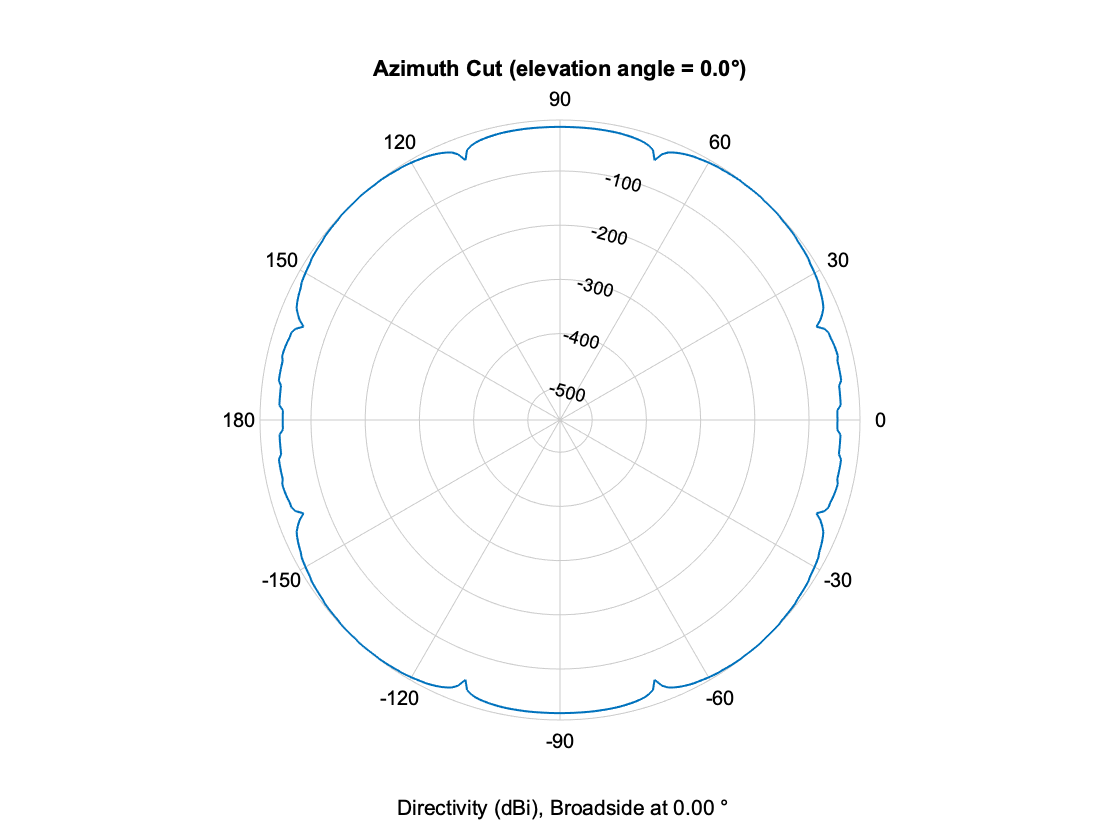

% Show an azimuthal cut of the array ’s beam pattern .
figure
patternAzimuth(arbitrary,fc)

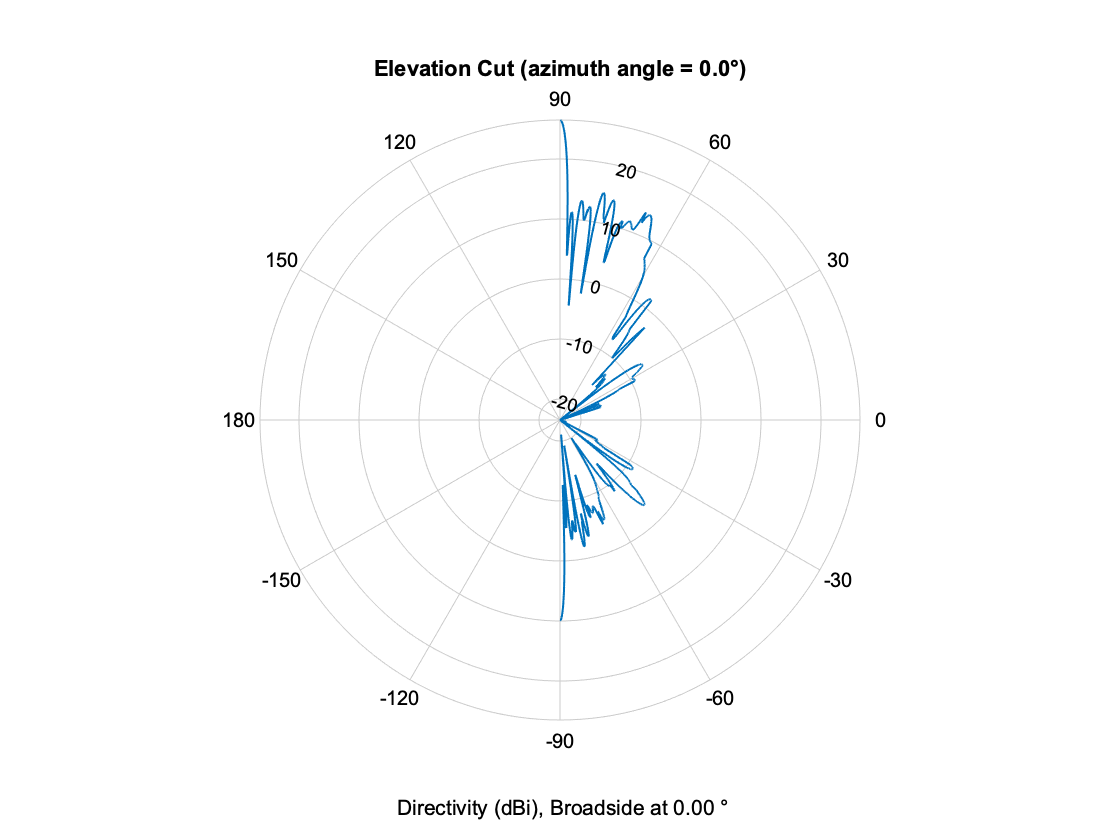

% Show an elevation cut of the array ’s beam pattern .
figure
patternElevation(arbitrary,fc ,'Elevation' , -90:0.01:90) ;